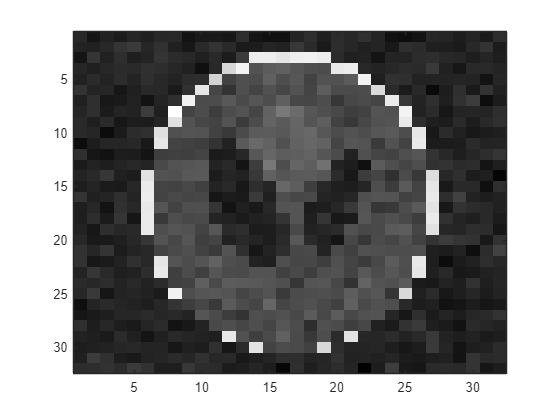

GT=phantom("modified Shepp-Logan",32);

kspace=fftshift(fft2(GT));
repetition=10;

GT_noise=add_gaussian_noise(GT,0.05,repetition);

imagesc(squeeze(real(GT_noise(1,:,:))));
colormap gray;

arranged_GT_noise=reshape(GT_noise,10,[]);

mean=sum(arranged_GT_noise,1)/repetition;
shifted_arranged_GT_noise=arranged_GT_noise-mean;

C=cov(shifted_arranged_GT_noise);
[evector,evalue]=eig(C);


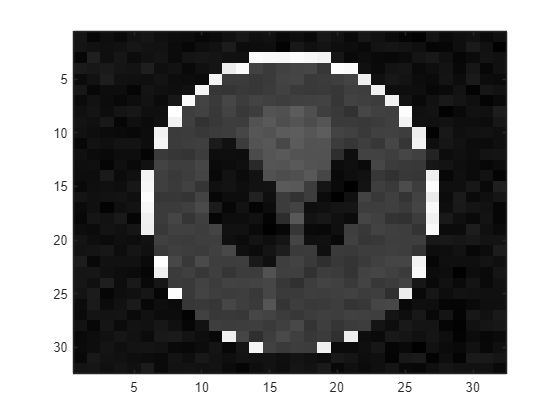

[~,index]=max(diag(evalue));
u_principal=evector(:,index);

temp=shifted_arranged_GT_noise*u_principal;
recon=temp*u_principal';

figure;
recon1=squeeze(recon(1,:))+mean;
imagesc(real(reshape(recon1,32,32)));
colormap gray;


MSE=(sum((recon-reshape(GT,1,[])).^2,"all")/(32^2))^1/2;
disp(MSE);

   0.3040 + 0.0001i



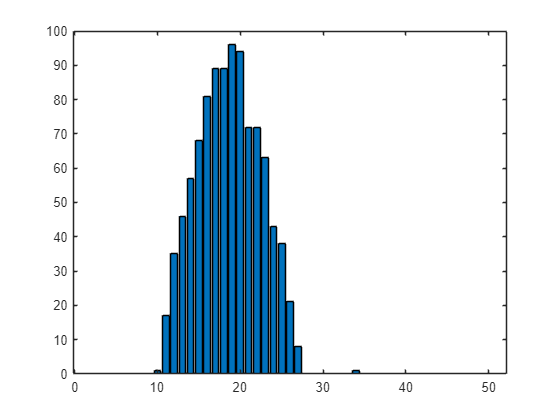

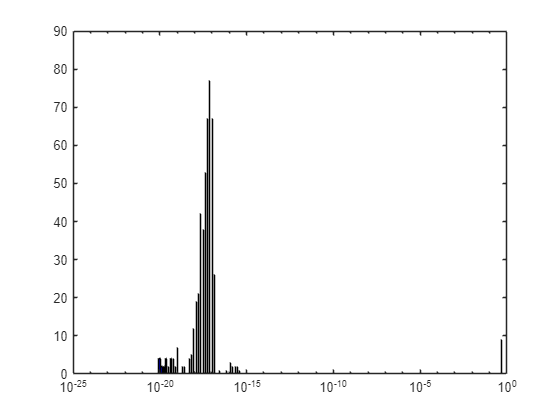

% Count

evalues=diag(evalue);

min_ev=min(evalues);
max_ev=max(evalues);
step=(max_ev-min_ev)/30e16;
count_ev=zeros(1,40);

for i=1:400
    if i==400
        count_ev(i)=sum((evalues>=((i-1)*step+min_ev))&(evalues<=(i*step+min_ev)));
    end
    count_ev(i)=sum((evalues>=((i-1)*step+min_ev))&(evalues<(i*step+min_ev)));
end
figure;
bar(count_ev(250:300))